# Graphene Euler-Bernoulli beam (dynamic, 1d)

**Notes**: 

Literature: mini switches, magnetic resonator, physical measures

Lee's paper, MIT wave guide

## Global constants

% from Lee, D. Wei's paper
L = 1; % length of the beam
rho = 1; % density of the material
E = 1; % young's modulus
sigma_max = .13;
D = -5*(E^2)/(4*sigma_max); % nonlinear elastic modulus
I1 = 1; % moment of inertia
I2 = 0.02; % moment of inertia
% F = 10e6; % external force
F = -2;

A = 1; % cross-section area (b*h)
B = E*I1;
C = D*I2;
C3 = 1/(12*C^2*F)*(6*B*C*F*L - B^3 + (B^2-4*C*F*L)^(3/2));
C4 = 1/(12*C^2*F)*(B^3*L -3*B*C*F*L^2 + 1/(10*C*F)*((B^2-4*C*F*L)^(5/2) - B^5)) + L*C3;

## FEM config

Nb = 4; % number of dof per element
gauss_points_num = 8;
master = [0 1];
Npts = 100; % for plotting

% linear elements
coeffs =   [1,0,-3,2; 
            0,1,-2,1;
            0,0,3,-2;
            0,0,-1,1];

## Matrix assembly

NEL = 20;
h = L/NEL;

% basis functions on the master element
N = basis_functions(coeffs);
d2_N = basis_derivatives(coeffs, 2);
d3_N = basis_derivatives(coeffs, 3);

% global nodes
xs = linspace(0,L,NEL+1);

% mesh sizes
hs = zeros(NEL,1);
for i=1:NEL
    hs(i) = xs(i+1) - xs(i);
end

% element nodes
es = zeros(NEL,2);
for i=1:NEL
    es(i,:) = [xs(i) xs(i+1)];
end

% local stiffness and mass matrices
Kl = zeros(Nb,Nb,NEL);
Ml = zeros(Nb,Nb,NEL);
fl = zeros(Nb,1,NEL);
for k=1:NEL
    for i=1:Nb
        for j=1:Nb
            Kl(i,j,k) = 1 / (hs(k))^3 * gauss(@(x) d2_N(i,x) * d2_N(j,x), master(1), master(2), gauss_points_num);
            Ml(i,j,k) =      hs(k)    * gauss(@(x)    N(i,x) *    N(j,x), master(1), master(2), gauss_points_num);
        end
        fl(i,1,k)     = F *  hs(k)    * gauss(@(x) N(i,x), master(1), master(2), gauss_points_num);
    end
end

% Global matrices and force term
Kn = (NEL+1)*2;
K = zeros(Kn,Kn); M = zeros(Kn,Kn);
f = zeros(Kn,1);

for i=1:NEL
    K(2*i-1:2*i+Nb-2,2*i-1:2*i+Nb-2) = K(2*i-1:2*i+Nb-2,2*i-1:2*i+Nb-2) + Kl(1:Nb,1:Nb,i);
    M(2*i-1:2*i+Nb-2,2*i-1:2*i+Nb-2) = M(2*i-1:2*i+Nb-2,2*i-1:2*i+Nb-2) + Ml(1:Nb,1:Nb,i);
    f(2*i-1:2*i+Nb-2,1) = f(2*i-1:2*i+Nb-2,1) + fl(1:Nb,1,i);
end

K1 = E*I1*K;
K2 = D*I2*K;

M = rho*M;

## Solver prep

T0 = 0; 
Tf = 2.5e0;
tau = 2e-2; 

Ntsteps = round(Tf/tau+1);

lambda = tau^2;

Amat = M+lambda/4*K1;
Bmat = 2*M-lambda/2*K1;
f = lambda*f;

Amat(1,:) = []; Amat(:,1) = []; Amat(end-1,:) = []; Amat(:, end-1) = [];
Bmat(1,:) = []; Bmat(:,1) = []; Bmat(end-1,:) = []; Bmat(:, end-1) = [];
K1(1,:) = []; K1(:,1) = []; K1(end-1,:) = []; K1(:, end-1) = [];
K2(1,:) = []; K2(:,1) = []; K2(end-1,:) = []; K2(:, end-1) = [];

Amat = sparse(Amat);
Bmat = sparse(Bmat);
K1 = sparse(K1);
K2 = sparse(K2);
f(1) = []; f(end-1) = [];

vs = zeros(Kn,1);
ws = zeros(Kn,1);
% Use fixed point iteration for u
% Start with the initial guess
us = zeros(Kn-2,Ntsteps);
usf = zeros(Kn,Ntsteps);
usf(:,1) = vs;
us(1:end-1,1) = vs(2:end-2,1); us(end,1) = vs(end,1);

% implicit scheme
options = optimset('Display','off');

func1 = @(soln) 2*Amat*soln - (Bmat*us(:,1) + 2*tau*Amat*[ws(2:end-2,1);ws(end,1)] + f - lambda*K2*hfun(([0;soln(1:end-1,1);0;soln(end,1)] + usf(:,1) - tau*ws)/2));
us(:,2) = fsolve(func1, ones(Kn-2,1),options);
usf(:,2) = [0;us(1:end-1,2);0;us(end,2)];

for j=3:Ntsteps
    func2 = @(soln) Amat*soln - (Bmat*us(:,j-1) - Amat*us(:,j-2) + f - lambda*K2*hfun(([0;soln(1:end-1,1);0;soln(end,1)] + 2*usf(:,j-1) + usf(:,j-2))/4));
    us(:,j) = fsolve(func2,ones(Kn-2,1),options);
    usf(:,j) = [0;us(1:end-1,j);0;us(end,j)];
end

us2 = zeros(Kn-2,Ntsteps);
us2(1:end-1,1) = vs(2:end-2,1); us2(end,1) = vs(end,1);

us2(:,2) = (2*Amat)\(Bmat*us2(:,1) + 2*tau*Amat*[ws(2:end-2,1);ws(end,1)] + f);

for j=3:Ntsteps
    us2(:,j) = Amat\(Bmat*us2(:,j-1) - Amat*us2(:,j-2) + f);
end
us2f = [zeros(1,Ntsteps); us2(1:end-1,:); zeros(1,Ntsteps); us2(end,:)];

% steady-state
% func_ss = @(x) K1*x + K2*hfun([0;x(1:end-1);0;x(end)]) - f;
% us_ss = fsolve(func_ss, ones(length(K)-2,1), options);
% us_ss = [0;us_ss(1:end-1);0;us_ss(end)];
% 
% uslin_ss = K1\f;
% uslin_ss = [0;uslin_ss(1:end-1);0;uslin_ss(end)];

xxxs = linspace(0,L,Npts);
u_full = zeros(length(xxxs),Ntsteps);
u_full2 = zeros(length(xxxs),Ntsteps);

for j=1:Ntsteps
    % local u coefficients
    u_locals = zeros(NEL, Nb);
    for i=1:NEL
        u_locals(i,1:end) = usf(2*i-1: 2*i+Nb-2,j);
    end
    
    u_locals2 = zeros(NEL, Nb);
    for i=1:NEL
        u_locals2(i,1:end) = us2f(2*i-1: 2*i+Nb-2,j);
    end
    
    % producing piecewise polynomial approximation
    
    u_vals = zeros(length(xxxs),1);
    for i=1:length(xxxs)
        u_vals(i) = u_fun(u_locals, xxxs(i), NEL, Nb, N, es, xs);
    end
    u_full(1:end,j) = u_vals;
    
    u_vals2 = zeros(length(xxxs),1);
    for i=1:length(xxxs)
        u_vals2(i) = u_fun(u_locals2, xxxs(i), NEL, Nb, N, es, xs);
    end
    u_full2(1:end,j) = u_vals2;
end

% steady-state

% uss_locals = zeros(NEL, Nb);
% usslin_locals = zeros(NEL, Nb);
% for i=1:NEL
%     uss_locals(i,:) = us_ss(2*i-1: 2*i+Nb-2);
%     usslin_locals(i,:) = uslin_ss(2*i-1: 2*i+Nb-2);
% end
% 
% uss_vals = zeros(length(xxxs),1);
% usslin_vals = zeros(length(xxxs),1);
% for i=1:length(xxxs)
%     uss_vals(i) = u_fun(uss_locals, xxxs(i), NEL, Nb, N, es, xs);
%     usslin_vals(i) = u_fun(usslin_locals, xxxs(i), NEL, Nb, N, es, xs);
% end
% uss_full = uss_vals;
% usslin_full = usslin_vals;

## Plotting

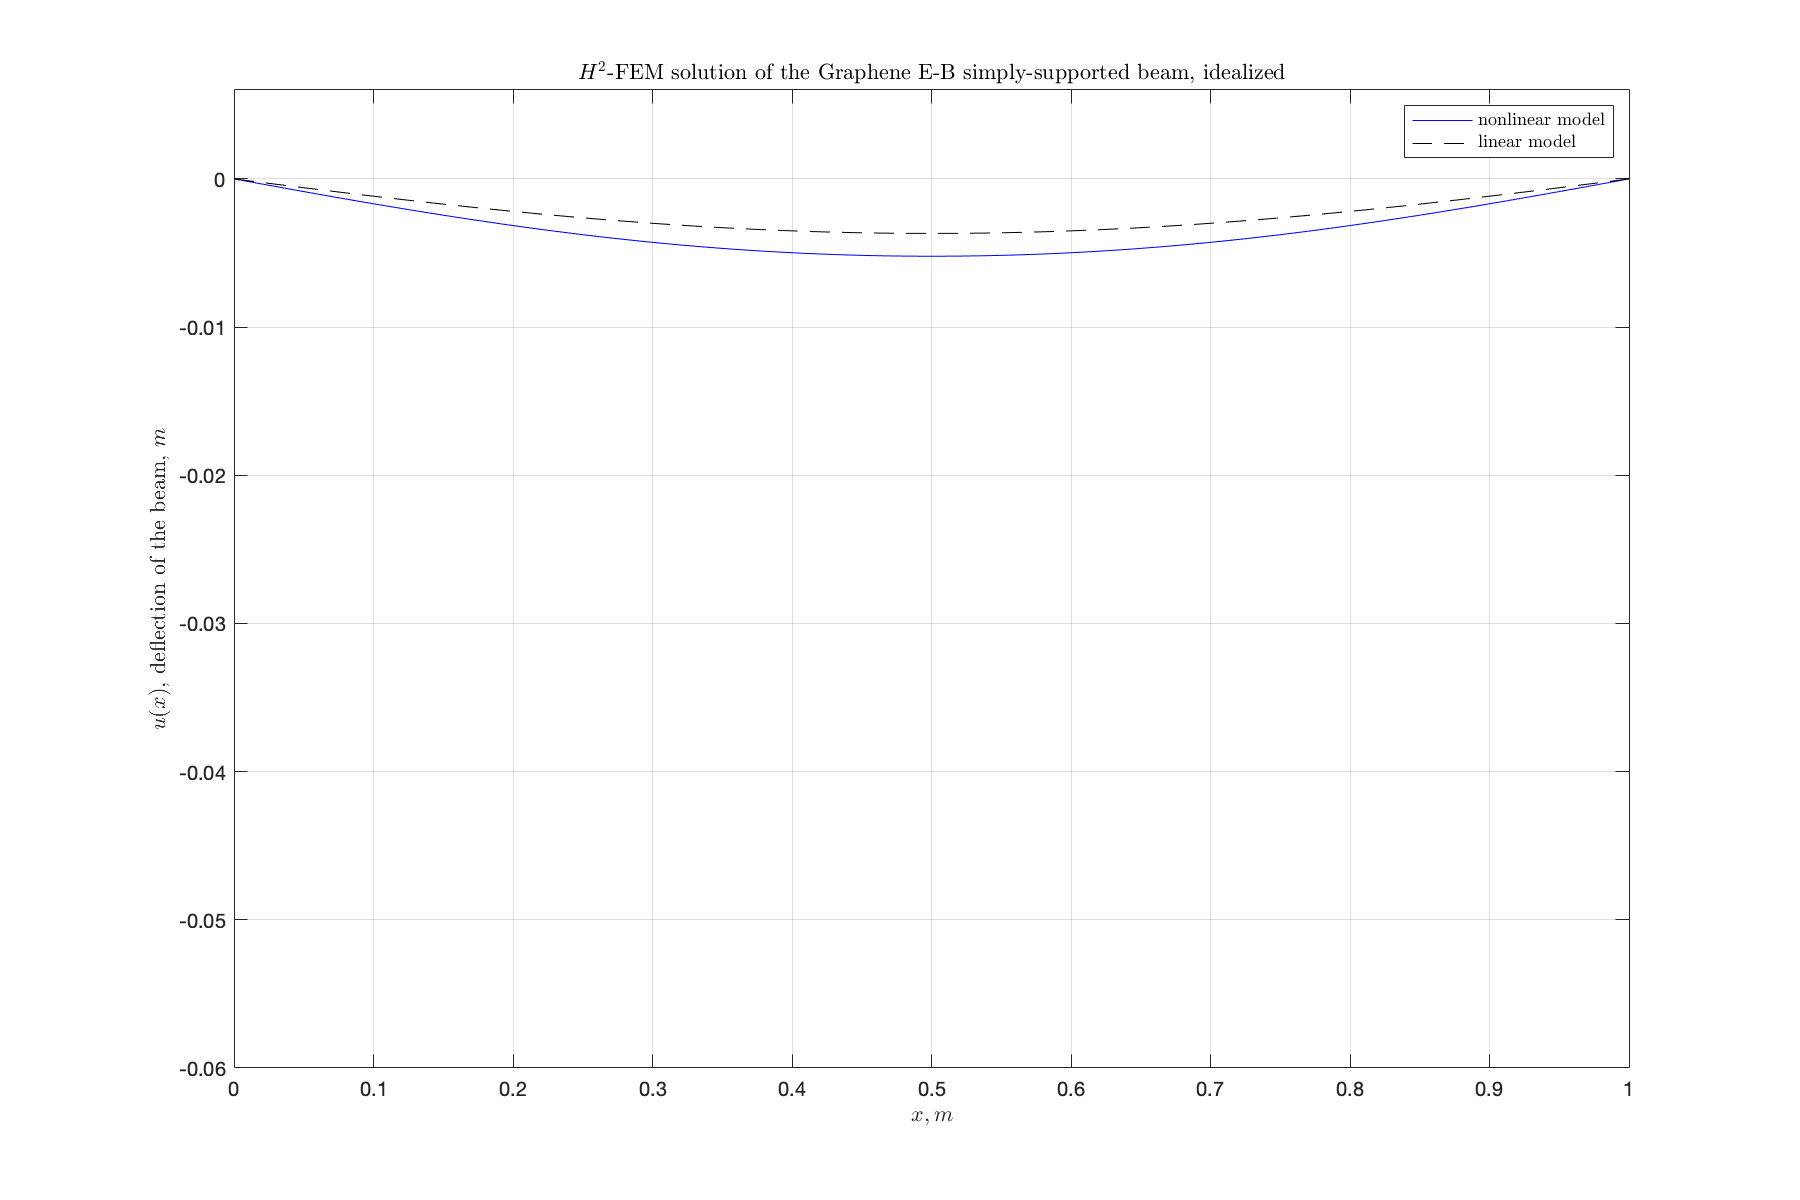

% figure
figure('Position', [10 10 900 600])
ampl = 6e-2;
for j=1:Ntsteps
%     plot(xxxs,u_full(1:end,j),'b-', xxxs,u_full2(1:end,j),'r-', xxxs,uss_full,'b--', xxxs,usslin_full,'r--')
    plot(xxxs,u_full(1:end,j),'b-', xxxs,u_full2(1:end,j),'k--')
    grid on
    xlim([0 L])
    
    ylim([-ampl,ampl/10])
    title("$H^2$-FEM solution of the Graphene E-B simply-supported beam, idealized", "Interpreter","latex")
    
    xlabel('$x, m$', "Interpreter","latex")
    ylabel('$u(x)$, deflection of the beam, $m$', "Interpreter","latex")
    
%     leg = legend('nonlinear model','linear model','nonlinear steady-state', 'linear steady-state');    
    leg = legend('nonlinear model','linear model');
    set(leg,'Interpreter','latex');    
    
    hold off
    pause(.05)
end

## FEM tools

function res = chi(e,x,xs) 
    res = false;
    if x > xs(e) && x <= xs(e+1)
        res = true;
    end
end

function res = xi(x,xe)
     res = (x - xe(1)) / (xe(2) - xe(1));
end

% assemble u(x) from u_i coefficients
function res = u_fun(u_locals, x, NEL, Nb, N, es, xs)
    res = 0;
    for i=1:NEL
        sm = 0;
        for j=1:Nb
            sm = sm + u_locals(i,j) * N(j,xi(x,es(i,:)));
        end
        sm = sm * chi(i,x,xs);
        res = res + sm;
    end
end

## Polynomial tools

function basis = basis_functions(coefficient_matrix)
    mat_size = length(coefficient_matrix);
    basis = @(index, x) coefficient_matrix(index,1:mat_size)*(x.^(0:mat_size-1))';
end

function der_mat = derivative_matrix(basis_order, derivative_order)
    der_mat = zeros(basis_order, basis_order);
    for i=derivative_order+1:basis_order
        prod = 1;
        for j=1:derivative_order
            prod = prod*(i-j);
        end
        der_mat(i-derivative_order,i) = prod;
    end
    der_mat = sparse(der_mat');
end

function res = basis_derivatives(coefficient_matrix, order)
    der_mat = derivative_matrix(length(coefficient_matrix), order);
    res = basis_functions(coefficient_matrix*der_mat);
end

function res = gauss(fun, a, b, order)
    [x,w] = lgwt(order,a,b);
    f = arrayfun(fun,x);
    res = sum(f.*w);
end

## Projection onto FE space

function proj = project(fun, dfun, xs)
    proj = zeros(2*length(xs),1);
    for i=1:length(xs)
        proj(2*i-1) =  fun(xs(i));
        proj(2*i)   = dfun(xs(i));
    end
end

function res = hfunc(x)
    res = abs(x)*x;
end

function res = d_hfunc(x)
    res = 2*abs(x);
end

% p-laplacian
function res = hfun(x)
    n = length(x);
    res = zeros(n,1);
    for i=1:n
        if rem(i, 2) == 1
            res(i) = hfunc(x(i));
        else
            res(i) = d_hfunc(x(i-1))*x(i);
        end
    end
    res(1) = []; res(end-1) = [];
end
